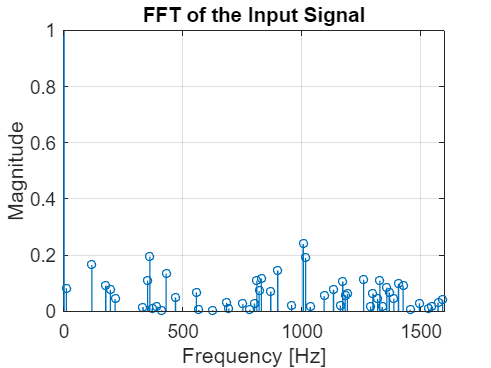

% Plot output_fft_mag vs output_freq
% arm_cmplx_mag_f32 calculates complex mag. fft of the signal with a length of
% FFT_LENGTH/2

fid = fopen('OutputFFT_for8.bin'); % put the correct file name
spectrum = fread(fid,inf,'float'); 
fclose(fid);

fid = fopen('FrequencyFFT_for8.bin'); % put the correct file name
freq = fread(fid,inf,'float'); 
fclose(fid);

figure; 
stem(freq,spectrum,'LineWidth',1);


set(gca,'FontSize',14)
grid on;
xlabel('Frequency [Hz]','FontSize',16);
ylabel('Magnitude','FontSize',16);  
title('FFT of the Input Signal');  % This is the title of the plot (modify for each different plot)

% After your plotting code, add:
ylim([0 1]);   % Matches the scale shown in your image
xlim([0 1600]); % Sets x-axis to match your frequency range